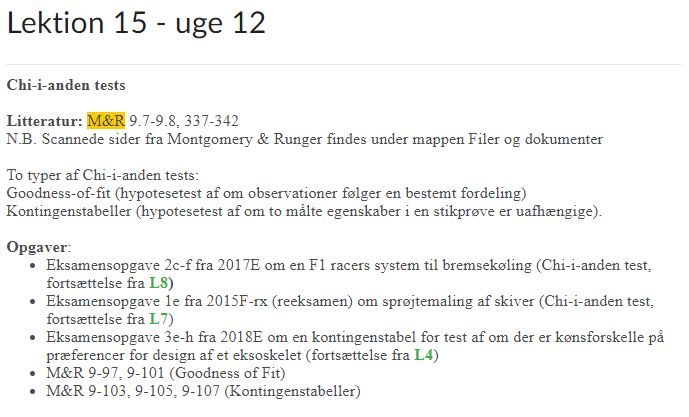

clc; clear;

% noget poisson gøgl

dist = makedist("Poisson","lambda",10)

dist =   PoissonDistribution

  Poisson distribution
    lambda = 10



x = 0:0.1:20

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000



pd = pdf(dist, x)

pd =     0.0000         0         0         0         0         0         0         0         0         0    0.0005         0         0         0         0         0         0         0         0         0    0.0023         0         0         0         0         0         0         0         0         0    0.0076         0         0         0         0         0         0         0         0         0    0.0189         0         0         0         0         0         0         0         0         0


pds = find(pd ~= 0)

pds =      1    11    21    31    41    51    61    71    81    91   101   111   121   131   141   151   161   171   181   191   201



for i = 1:length(pds)
    ps(i) = pd(pds(i));
end

xs = 1:length(pds)

xs =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21


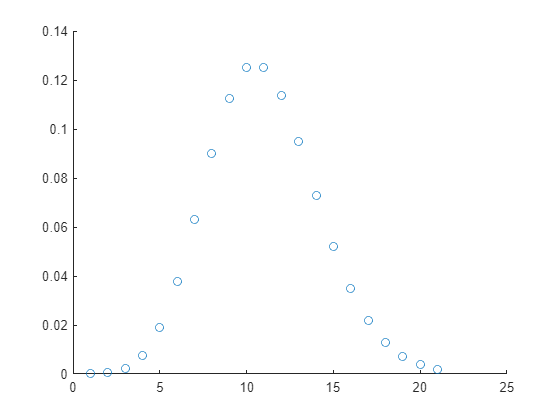


scatter(xs, ps)